# TALLER MRAC - AERONAVE JAXA MuPAL

Ejecutar este archivo desde la carpeta del proyecto.

clear; clc; close all;

## 1. Datos y comprobaciones iniciales

p = datos_jaxa();
if ~exist(p.carpeta_figuras,'dir'), mkdir(p.carpeta_figuras); end
if ~exist(p.carpeta_resultados,'dir'), mkdir(p.carpeta_resultados); end

ac = analizar_acoplamiento(p);


================ ANÁLISIS DE ACOPLAMIENTO ================
Rango de controlabilidad de (A,B): 4 de 4
Kx ideal aproximada (mínimos cuadrados):
    0.0285    0.0142 -316.4669 -100.2891

kr ideal aproximada: 322.6504217941
||Am-(A+B*Kx)||_F = 7.816855e-02
Error relativo de Am = 3.651959e-05
||Bm-B*kr||_2 = 2.115183e-02
Error relativo de Bm = 1.010360e-05
Autovalores de A:
  -1.4940 + 2.1542i  -1.4940 - 2.1542i  -0.0097 + 0.1805i  -0.0097 - 0.1805i

Autovalores de Am:
 -421.9808   -3.1703   -0.0528   -0.9661




## 2. Simulación independiente del modelo de referencia

sim_ref = simular_modelo_referencia(p,p.t_step,'step');
graficar_modelo_referencia(sim_ref,p,'paso');

## 3. MRAC con entrada paso

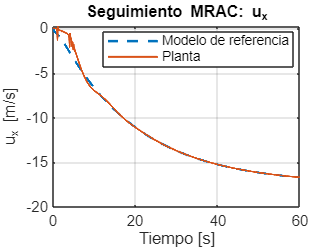

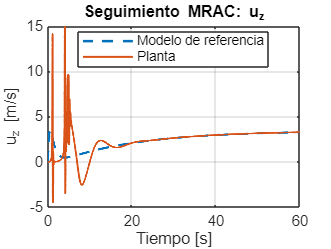

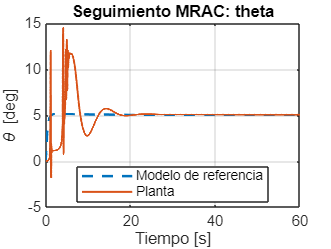

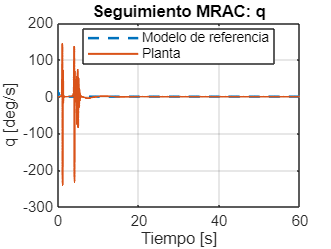

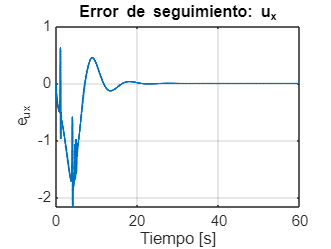

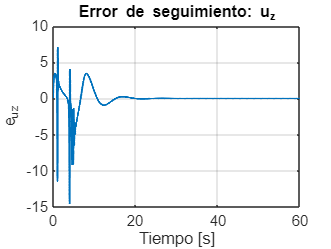

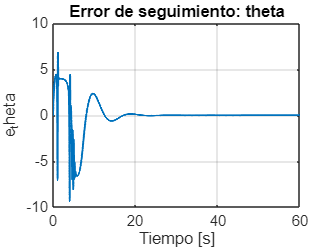

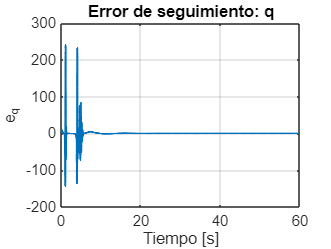

sim_step = simular_mrac(p,ac,p.t_step,'step',p.Gamma_x,p.gamma_r,false);
graficar_mrac(sim_step,p,'mrac_paso');


fprintf('\n================ RESULTADOS: PASO ================\n');


================ RESULTADOS: PASO ================


fprintf('Kx final = [% .8f % .8f % .8f % .8f]\n',sim_step.Kx_final);

Kx final = [-1.69934831 -8.70093228 -0.10252245 -0.15603007]


fprintf('kr final = %.8f\n',sim_step.kr_final);

kr final = 1.58254594


fprintf('||e(tf)||_2 = %.6e\n',sim_step.norma_error_final);

||e(tf)||_2 = 8.625489e-03


fprintf('RMS(e_theta) = %.6f deg\n',rad2deg(sim_step.error_theta_rms));

RMS(e_theta) = 3.211937 deg


fprintf('max |u| = %.6f\n',sim_step.u_max);

max |u| = 39.014484


fprintf('Autovalores de A+B*Kx(tf):\n'); disp(sim_step.eig_Acl_final.');

Autovalores de A+B*Kx(tf):
 -22.8258 +43.5909i -22.8258 -43.5909i  -0.0043 + 0.0154i  -0.0043 - 0.0154i



## 4. MRAC con tren de pulsos

sim_pulse = simular_mrac(p,ac,p.t_pulse,'pulse',p.Gamma_x,p.gamma_r,false);
graficar_mrac(sim_pulse,p,'mrac_pulsos');

fprintf('\n============= RESULTADOS: TREN DE PULSOS =============\n');
fprintf('Kx final = [% .8f % .8f % .8f % .8f]\n',sim_pulse.Kx_final);
fprintf('kr final = %.8f\n',sim_pulse.kr_final);
fprintf('||e(tf)||_2 = %.6e\n',sim_pulse.norma_error_final);
fprintf('RMS(e_theta) = %.6f deg\n',rad2deg(sim_pulse.error_theta_rms));
fprintf('max |u| = %.6f\n',sim_pulse.u_max);
fprintf('Autovalores de A+B*Kx(tf):\n'); disp(sim_pulse.eig_Acl_final.');

## 5. Verificación teórica usando el modelo proyectado exactamente acoplable

sim_exacta = simular_mrac(p,ac,p.t_step,'step',p.Gamma_x,p.gamma_r,true);
fprintf('\n========= VERIFICACIÓN CON ACOPLAMIENTO EXACTO =========\n');
fprintf('||e(tf)||_2 = %.6e\n',sim_exacta.norma_error_final);
fprintf('Este caso elimina el pequeño residuo debido al redondeo de Am y Bm.\n');

## 6. Comparación de ganancias de adaptación

comparar_ganancias_adaptacion(p,ac);

## 7. Guardar resultados numéricos

save(fullfile(p.carpeta_resultados,'simulaciones_mrac.mat'), ...
    'p','ac','sim_ref','sim_step','sim_pulse','sim_exacta');

fprintf('\nProceso terminado. Revise las carpetas figuras/ y resultados/.\n');